## **数据整理**

update_mode = "cat"; % 可选择 "add" 或 "cat"
    %% 按照之前的想法，对每张图片进行平均
    session_idxall{1} = [14:16, 1:13];
    %session_idxall{2} = [1:13, 16, 15, NaN];%使用了第五天的数据用来代替
    session_idxall{2} = [1:13, 16, 15, 14];
    %session_idxall{3} = [1:14, NaN, 16];
    session_idxall{3} = [1:14, 15, 16];
    session_idxall{4} = [1:14, 16, 15,17];
    session_idxall{5} = [1:16];

for condition_all = 15
    % global all_data;
    % 设置更新模式
    
    % 初始化数据结构
    all_data = cell(1, 17);
    for condition = 1:17
        all_data{condition} = cell(1, 1405);
        for y = 1:1405
            all_data{condition}{2, y} = 0; % 初始化计数
        end
    end

    % 遍历每一天的数据
    for dayday = 1:5
        session_idx = session_idxall{dayday};
        ori_idx = cell(length(session_idx), 1);

        % 遍历每个会话
        for session = 1:length(session_idx)
            if session_idx(session) == condition_all
                if ~isnan(session_idx(session))
                    % 加载数据
                    load(sprintf('/home/dclab2/Ensemble coding/data/12%02ddata/DG2-u78%d-%03d-500Hz.mat', dayday + 8, dayday + 1, session - 1));
                    trailnum = 6916;
                    TrialStimID = reshape(Datainfo.Seq.StimID, [52, trailnum / 52])';
                    RealOrdid = [];
                    RealOrdbuffid = TrialStimID;
                    RealOrdbufferrorid = [];

                    % 处理响应代码
                    for kk = 1:length(Datainfo.VSinfo.sMbmInfo.respCode)
                        RealOrdid = [RealOrdid; RealOrdbuffid(kk, :)];
                        if Datainfo.VSinfo.sMbmInfo.respCode(kk) ~= 1
                            RealOrdbuffid = cat(1, RealOrdbuffid, RealOrdbuffid(kk, :));
                        end
                    end

                    RealTrialID = find(Datainfo.VSinfo.sMbmInfo.respCode == 1);
                    StimID = RealOrdid(RealTrialID, :);
                    StimID = StimID';

                    % 根据会话类型处理刺激ID
                    ori = processStimID(StimID, session_idx(session));
                    ori_idx{session} = ori;

                    % 初始化方向数据
                    orientation_data = cell(2, 1405);
                    for i = 1:1405
                        orientation_data{1, i} = [];
                        orientation_data{2, i} = 0;
                    end

                    % 遍历 trial 和 block，处理 MUA 数据
                    for trial = 1:133
                        for block = 1:4
                            window = (80 + 260 * (block - 1) + 1):(100 + 260 * (block - 1) + 1 + 150);

                            % 计算基线和 MUA
%                             LFP
                            baseline = squeeze(mean(Datainfo.trial_LFP(trial, 1:96, window(1):window(20)), 3));
                            MUA = squeeze(Datainfo.trial_LFP(trial, 1:96, window)) - baseline';
%                             MUA
%                             baseline = squeeze(mean(Datainfo.trial_MUA{2}(trial, 1:96, window(1)-80:window(1)), 3));
%                             MUA = squeeze(Datainfo.trial_MUA{2}(trial, 1:96, window)) - baseline';
                            orientation = StimID(1 + 13 * (block - 1), trial);

                            % 将 MUA 数据存入方向数据
                            if isempty(orientation_data{1, orientation})
                                orientation_data{1, orientation} = MUA;
                            else
                                if update_mode == "add"
                                    % 加法更新
                                    orientation_data{1, orientation} = orientation_data{1, orientation} + MUA;
                                elseif update_mode == "cat"
                                    % 拼接更新
                                    orientation_data{1, orientation} = cat(3, orientation_data{1, orientation}, MUA);
                                end
                            end

                            % 更新计数
                            orientation_data{2, orientation} = orientation_data{2, orientation} + 1;
                        end
                    end

                    % 更新 all_data
                    session_idxreal = session_idx(session);
                    all_data = updateAllData(all_data, session_idxreal, orientation_data, update_mode);
                    
                    % 清理变量
                    clearvars -except all_data session session_idx ori_idx session_idxall dayday update_mode condition_all
                    disp(session);
                end
            end
        end
    end
    all_data_new = all_data{1,condition_all};
    save((sprintf('/home/dclab2/data%d.mat',condition_all)),'all_data_new');
    disp(condition_all);
    clearvars -except condition session_idxall update_mode
end

位置 1 处的索引超出数组边界(不能超出 2)。
出错 decodingcode>updateAllData (第 792 行)
                    if isempty(all_data{session_idxreal}{block, y})

看每一张图片所在的位置是否会有较大的影响

update_mode = "cat"; % 可选择 "add" 或 "cat"
    %% 按照之前的想法，对每张图片进行平均
    session_idxall{1} = [14:16, 1:13];
    %session_idxall{2} = [1:13, 16, 15, NaN];%使用了第五天的数据用来代替
    session_idxall{2} = [1:13, 16, 15, 14];
    %session_idxall{3} = [1:14, NaN, 16];
    session_idxall{3} = [1:14, 15, 16];
    session_idxall{4} = [1:14, 16, 15,17];
    session_idxall{5} = [1:16];

for condition_all = 15
    % global all_data;
    % 设置更新模式
    
    % 初始化数据结构
    all_data = cell(1, 17);
    for condition = 1:17
        all_data{condition} = cell(19, 19);
        for y = 1:19
            for ori_1 = 1:19
            all_data{condition}{ori_1, y} = []; % 初始化计数
          
            end
        end
    end

    % 遍历每一天的数据
    for dayday = 1:5
        session_idx = session_idxall{dayday};
        ori_idx = cell(length(session_idx), 1);

        % 遍历每个会话
        for session = 1:length(session_idx)
            if session_idx(session) == condition_all
                if ~isnan(session_idx(session))
                    % 加载数据
                    load(sprintf('/home/dclab2/Ensemble coding/data/12%02ddata/DG2-u78%d-%03d-500Hz.mat', dayday + 8, dayday + 1, session - 1));
                    trailnum = 6916;
                    TrialStimID = reshape(Datainfo.Seq.StimID, [52, trailnum / 52])';
                    RealOrdid = [];
                    RealOrdbuffid = TrialStimID;
                    RealOrdbufferrorid = [];

                    % 处理响应代码
                    for kk = 1:length(Datainfo.VSinfo.sMbmInfo.respCode)
                        RealOrdid = [RealOrdid; RealOrdbuffid(kk, :)];
                        if Datainfo.VSinfo.sMbmInfo.respCode(kk) ~= 1
                            RealOrdbuffid = cat(1, RealOrdbuffid, RealOrdbuffid(kk, :));
                        end
                    end

                    RealTrialID = find(Datainfo.VSinfo.sMbmInfo.respCode == 1);
                    StimID = RealOrdid(RealTrialID, :);
                    StimID = StimID';

                    % 根据会话类型处理刺激ID
                    ori = processStimID(StimID, session_idx(session));
                    ori_idx{session} = ori;

                    % 初始化方向数据
                    orientation_data = cell(19, 19);
                    for i = 1:19
                        for ori_1 = 1:19
                            orientation_data{ori_1, i} = [];
                        end
                    end
                    % 遍历 trial 和 block，处理 MUA 数据
                    for trial = 1:133
                        for block = 2:4
                            window = (80 + 260 * (block - 1) + 1):(100 + 260 * (block - 1) + 1 + 150);

                            % 计算基线和 MUA
%                             LFP
                            baseline = squeeze(mean(Datainfo.trial_MUA{2}(trial, 1:96, window(1):window(20)), 3));
                            MUA = squeeze(Datainfo.trial_MUA{2}(trial, 1:96, window)) - baseline';
%                             MUA
%                             baseline = squeeze(mean(Datainfo.trial_MUA{2}(trial, 1:96, window(1)-80:window(1)), 3));
%                             MUA = squeeze(Datainfo.trial_MUA{2}(trial, 1:96, window)) - baseline';
                            orientation = ori(1 + 13 * (block - 1), trial);
                            orientation_1 = ori(1 + 13 * (block - 2), trial);
                            % 将 MUA 数据存入方向数据
                            if isempty(orientation_data{1, orientation})
                                orientation_data{1, orientation} = MUA;
                            else
                                if update_mode == "add"
                                    % 加法更新
                                    orientation_data{1, orientation} = orientation_data{1, orientation} + MUA;
                                elseif update_mode == "cat"
                                    % 拼接更新
                                    orientation_data{orientation_1, orientation} = cat(3, orientation_data{orientation_1, orientation}, MUA);
                                end
                            end

                            % 更新计数
                            %orientation_data{2, orientation} = orientation_data{2, orientation} + 1;
                            
                        end
                    end

                    % 更新 all_data
                    session_idxreal = session_idx(session);
                    all_data = updateAllData(all_data, session_idxreal, orientation_data, update_mode);
                    
                    % 清理变量
                    clearvars -except all_data session session_idx ori_idx session_idxall dayday update_mode condition_all
                    disp(session);
                end
            end
        end
    end
    all_data_new = all_data{1,condition_all};
    %save((sprintf('/home/dclab2/data%d.mat',condition_all)),'all_data_new');
    disp(condition_all);
    %clearvars -except condition session_idxall update_mode
end

     2
    15
    15
    16
    15


    15


data0 = [];

for ori= 1:18
    for block = 1:4
        data1 = [];
        for i = 1:6
            if ~isempty(all_data_new{block,(i-1)*18+ori})
            data1 = cat(3,data1,all_data_new{block,(i-1)*18+ori});
            end
        end
        
        data0(ori,block,:,:) = squeeze(mean(data1,3));
    end
end

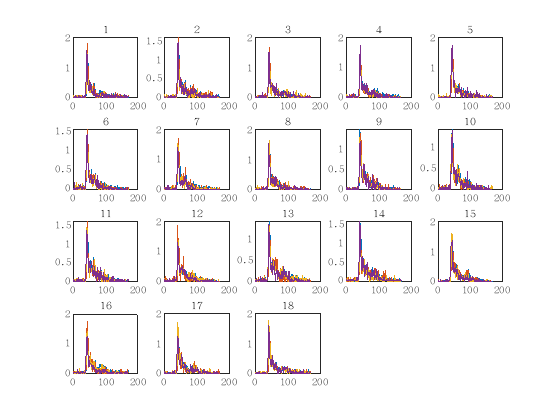

for ori =1:18
    subplot(4,5,ori);
    for i = 1:4
        plot(squeeze(data0(ori,i,18,:)));
        hold on
    end
    hold off
    subtitle(ori)
end

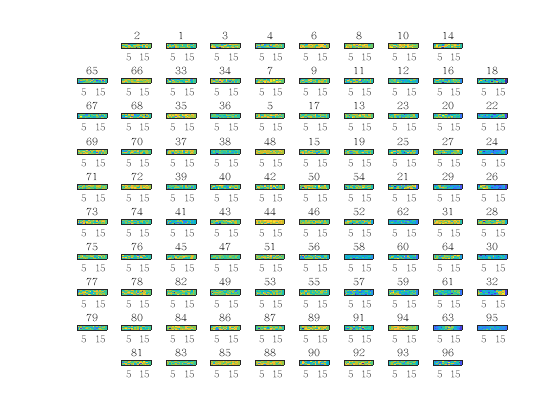


for x = 1:19
    for y = 1:19
        if ~isempty(all_data_new{x,y})
            data0(x,y,:) = squeeze(mean(mean(all_data_new{x,y},3),2));
        else
            for coil = 1:96
                data0(x,y,coil) = 0;
            end
        end
    end
end
for coil = 1:96
    load('Ensemble coding/data/chanmap.mat');
    n = find(ChanMap ==coil);
    subplot(10,10,n);
    imagesc(squeeze(data0(:,:,63)));
    subtitle(coil)
end

## PID解码

### 1）构建统一的数据：ori, repeat, coil,time

window = 1:101; % 窗口范围
num_trials = 18; % 每组的试验数
num_repeats = 6; % 每个试验组的重复数
minrepeat = 200; % 初始化最小重复数

condition = "EC";


if condition == "EC"
    num = arrayfun(@(i) sum(cell2mat(all_data_new(2, (i-1)*3+1 : i*3))), 1:108);
else
    if condition == "Patch"
        b = 1296;
    else
        b = 0;   
    end
    % 计算索引数组 idx
    idx1 = repmat(1:num_trials, num_repeats, 1)';
    idx2 = repmat(0:num_trials:num_trials * (num_repeats - 1), num_trials, 1);
    idx = reshape((idx1 + idx2)', 1, []); % 转换为行向量

    % 提取 `num` 数据，并重新排列顺序
    num = cellfun(@(x) x, all_data_new(2, (b+1):(b+108))); % 提取数据
    num = num(idx); % 按照索引重新排序
end

% 计算每组的重复次数，并找到最小重复数
repeat_counts = arrayfun(@(i) sum(num((i - 1) * num_repeats + 1:i * num_repeats)), 1:num_trials);
minrepeat = min([repeat_counts, minrepeat]); % 更新最小重复数

% 初始化结果矩阵
data = zeros(num_trials, minrepeat, 96, length(window));

% 组装数据
if condition == "EC"
    for i = 1:num_trials
        data1 = [];
        for m = 1:18
            idx = (i-1)*18+m;
            current_data = squeeze(all_data_new{1, idx}(:, window, :)); % 提取当前片段
        
            if isempty(data1)
                data1 = current_data; % 初始化 data1
            else
                data1 = cat(3, data1, current_data); % 沿第 3 维拼接
            end
        end
        data1 = permute(data1,[3,1,2]);
    data(i, :, :, :) = data1(1:minrepeat, :, :);%第4维是窗口       
    end
else
    for i = 1:num_trials
        data1 = [];
        for m = 1:num_repeats
            idx = b + (m - 1) * num_trials + i; % 索引计算
            current_data = squeeze(all_data_new{1, idx}(:, window, :)); % 提取当前片段

            if isempty(data1)
                data1 = current_data; % 初始化 data1
            else
                data1 = cat(3, data1, current_data); % 沿第 3 维拼接
            end
        end
        % 选取前 minrepeat 个重复
        data1 = permute(data1,[3,1,2]);
        data(i, :, :, :) = data1(1:minrepeat, :, :);%第4维是窗口
    end
end


%通道筛选
load('/home/dclab2/SNR.mat','coilSNR');
[~,coilidx] = sort(coilSNR,'descend');
coilselect = coilidx(1:12);
data0 = zeros(18,140,length(coilselect),101);
for coil = 1:length(coilselect)
    data0(:,:,coil,:) =data(:,:,coilselect(coil),:) ;
end

### 2)解码

% data0 = data0Copy([1,2],:,:,:);
% clearvars -except data0 data data0Copy
% 参数设置
num_orientations = 2;
num_iterations = 50; % 交叉验证的重复次数
k = 5; % K折交叉验证


[~, num_trials, ~, num_time_points] = size(data0); % 数据维度

% 初始化存储每次交叉验证的解码准确率
accuracy_all = zeros(num_iterations, num_time_points);
accuracy_chance = zeros(num_iterations, num_time_points);
chancelevel = zeros(num_iterations, num_time_points);
predictions = cell(num_time_points,num_iterations);
predictions_chance = cell(num_time_points,num_iterations);
true_labels = cell(num_time_points,num_iterations);

% 100次交叉验证
for iter = 1:num_iterations
    fprintf('正在进行第 %d 次交叉验证...\n', iter);

    % K折交叉验证分组
    indices = crossvalind('Kfold', num_trials, k);
   
    % 对每个时间点进行解码
    for t = 1:num_time_points
        % 记录每次交叉验证的预测和真实标签
        predictions{t,iter} = [];
        true_labels{t,iter} = [];

        for fold = 1:k
            % 划分训练集和测试集（取当前时间点的数据）
            train_data = data0(:, indices ~= fold, :, t);
            test_data = data0(:, indices == fold, :, t);
            
            % 计算调谐曲线
            f_theta_est = squeeze(mean(train_data, 2));
            f_theta_est = imgaussfilt(f_theta_est, 1);
            f_theta_est = max(f_theta_est, 1e-6); % 避免对数问题

            % 对测试集进行解码
            for theta = 1:num_orientations
                for trial = 1:sum(indices == fold)
                    response = squeeze(test_data(theta, trial, :))';
                    log_likelihoods = compute_log_likelihood_poisson(response, f_theta_est);
                    [~, predicted_orientation] = max(log_likelihoods);
                    predictions{t,iter} = [predictions{t,iter}; predicted_orientation];
                    true_labels{t,iter} = [true_labels{t,iter}; theta];
                    %chance-level
                    response_chance = squeeze(test_data(randi(num_orientations), randi(length(test_data(1,:,1))), :))';
                    log_likelihoods_chance = compute_log_likelihood_poisson(response_chance, f_theta_est);
                    [~, predicted_orientation_chance] = max(log_likelihoods_chance);
                    predictions_chance{t,iter} = [predictions_chance{t,iter}; predicted_orientation_chance];
                end
            end
        end

        % 存储当前时间点的解码准确率
        accuracy_all(iter, t) = mean(predictions{t,iter} == true_labels{t,iter});
        accuracy_chance(iter, t) = mean(predictions_chance{t,iter} == true_labels{t,iter});
%         vector = true_labels{t,iter};
%         chancelevel(iter,t) = mean(predictions{t,iter} == vector(randperm(2520)));
    end
end
%save('/home/dclab2/data_1231/ECdecodingEC.mat','accuracy_all','predictions','true_labels','accuracy_chance')

figure;
a = [];
for n = 1:10
a = cat(1,predictions{1,n});
end
histogram(a,'Normalization', 'probability');

### 3）Shuffle的chance-level

% 假设数据已加载：accuracy_all (num_iterations × num_time_points)
% 和 chancelevel (num_iterations × num_time_points)
%accuracy_all = accuracy_all - mean(accuracy_all(:,1:14)-0.05,2);

chancelevel =accuracy_chance;
% 参数设置
num_iterations = size(accuracy_all, 1); % 迭代次数
num_time_points = size(accuracy_all, 2); % 时间点数量
alpha = 0.01; % 显著性水平
threshold = 0.056; % 显著性阈值

% 计算 accuracy_all 的均值和 95% 置信区间
mean_accuracy = mean(accuracy_all, 1); % 每个时间点的平均解码准确率
std_accuracy = std(accuracy_all, 0, 1); % 每个时间点的标准差
ci_upper_accuracy = mean_accuracy + 1.96 * (std_accuracy / sqrt(num_iterations)); % 95%置信区间上界
ci_lower_accuracy = mean_accuracy - 1.96 * (std_accuracy / sqrt(num_iterations)); % 95%置信区间下界

% 计算 chancelevel 的均值和 95% 置信区间
mean_chance = mean(chancelevel, 1); % 每个时间点的平均 chancelevel
std_chance = std(chancelevel, 0, 1); % 每个时间点的标准差
ci_upper_chance = mean_chance + 1.96 * (std_chance / sqrt(num_iterations)); % 95%置信区间上界
ci_lower_chance = mean_chance - 1.96 * (std_chance / sqrt(num_iterations)); % 95%置信区间下界

% 显著性测试（accuracy 是否显著大于 chancelevel）
p_values = zeros(1, num_time_points);
significant_time_points = false(1, num_time_points);

for t = 1:num_time_points
    [~, p_values(t)] = ttest(accuracy_all(:, t), chancelevel(:, t), 'Alpha', alpha, 'Tail', 'right');
    if p_values(t) < alpha
        significant_time_points(t) = true; % 标记显著的时间点
    end
end
%figure;
i=4;
% 可视化：绘制 accuracy 和 chancelevel
%figure;
color1 = [130,176,210;255,190,122;250,127,111;142,207,201];
% 绘制 accuracy 的平均值折线和置信区间
plot(1:num_time_points, mean_accuracy,'Color', color1(i,:)/256, 'LineWidth', 1.5); hold on;
fill([1:num_time_points, fliplr(1:num_time_points)], ...
     [ci_upper_accuracy, fliplr(ci_lower_accuracy)], ...
     color1(i,:)/256, 'FaceAlpha', 0.2, 'EdgeColor', 'none');

% 绘制 chancelevel 的平均值折线和置信区间
plot(1:num_time_points, mean_chance, 'Color',[0.5,0.5,0.5], 'LineWidth', 1.5); % chancelevel 平均值折线
fill([1:num_time_points, fliplr(1:num_time_points)], ...
     [ci_upper_chance, fliplr(ci_lower_chance)], ...
     [0.5,0.5,0.5], 'FaceAlpha', 0.2, 'EdgeColor', 'none');

% 显著时间点可视化（accuracy 大于 chancelevel 的时间点）
y_min = 0; % 图表下界
y_max = 0.2; % 图表上界
for t = 1:num_time_points
    if significant_time_points(t)
        fill([t-0.5, t+0.5, t+0.5, t-0.5], [y_min+(i-1)*0.01, y_min+(i-1)*0.01, y_min+i*0.01, y_min+i*0.01], ...
             color1(i,:)/256, 'FaceAlpha', 0.5, 'EdgeColor', 'none'); % 用红色区块标记显著时间点
    end
end

% 图表设置
xlabel('时间点');
ylabel('解码准确率');
title('解码准确率、基线水平及显著性分析');
ylim([y_min, y_max]);
%grid on;

% 图例说明
% legend({'平均解码准确率', '95%置信区间（解码准确率）', ...
%     '平均基线水平', '95%置信区间（基线水平）', ...
%     '显著时间点'}, 'Location', 'best');
% hold off;



### 4）固定值chancelevel

% 计算均值和95%置信区间
mean_accuracy = mean(accuracy_all, 1); % 每个时间点的平均准确率
std_accuracy = std(accuracy_all, 0, 1); % 每个时间点的标准差
ci_upper = mean_accuracy + 1.96 * (std_accuracy / sqrt(num_iterations)); % 95%置信区间上界
ci_lower = mean_accuracy - 1.96 * (std_accuracy / sqrt(num_iterations)); % 95%置信区间下界
threshold = 0.056; % 显著性阈值
alpha = 0.05; % 显著性水平（对应于95%置信区间）
% 显著性测试（比较是否大于阈值 0.55）
p_values = zeros(1, num_time_points);
significant_time_points = false(1, num_time_points);

for t = 1:num_time_points
    [~, p_values(t)] = ttest(accuracy_all(:, t), threshold, 'Alpha', alpha, 'Tail', 'right');
    if p_values(t) < alpha
        significant_time_points(t) = true; % 标记显著的时间点
    end
end

% 可视化
figure;

% 绘制平均解码准确率折线
plot(1:num_time_points, mean_accuracy, '-b', 'LineWidth', 1.5); hold on;

% 绘制95%置信区间的浅色区域
fill([1:num_time_points, fliplr(1:num_time_points)], ...
     [ci_upper, fliplr(ci_lower)], ...
     'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');

% 在显著时间点下方标识（用红色区块）
y_min = 0; % 图表下界
y_max = 0.3; % 图表上界
for t = 1:num_time_points
    if significant_time_points(t)
        fill([t-0.4, t+0.4, t+0.4, t-0.4], [0, 0, 0.02, 0.02], ...
             'b', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
    end
end

% 图表设置
xlabel('时间点');
ylabel('解码准确率');
title('每个时间点的解码准确率及显著性');
ylim([y_min, y_max]);
grid on;
legend({'平均解码准确率', '95%置信区间', '显著大于 0.55'}, 'Location', 'best');

## SVM解码


clearvars -except data0 data
tic;
% 假设数据矩阵为 data0
[numOrientations, numRepeats, numChannels, numTimePoints] = size(data0);

labels = repelem((1:numOrientations)', numRepeats); % 标签
SVMModel = cell(1, numTimePoints);
accuracy = zeros(1, numTimePoints);
chance_level = zeros(1, numTimePoints);
chanceLevelDist = zeros(1, numTimePoints); % 记录随机打乱标签的准确率分布

% 定义用于交叉验证的参数
numFolds = 5; % K 折交叉验证
numShuffles = 100; % 随机打乱标签的次数

% 数据准备和训练
for t = 1:numTimePoints
    decodingdata = squeeze(data0(:, :, :, t)); % 提取每个时间点的数据
    
    % 数据重塑
    reshapedData = reshape(permute(decodingdata, [2, 1, 3]), [], numChannels); 
    
    % 交叉验证的初始划分
    cv = cvpartition(labels, 'KFold', numFolds);
    foldAccuracy = zeros(1, numFolds);
    foldchanceAccuracy = zeros(1, numFolds);
    % 交叉验证训练和评估
    for fold = 1:numFolds
        trainIdx = training(cv, fold);
        testIdx = test(cv, fold);
        
        XTrain = reshapedData(trainIdx, :);
        YTrain = labels(trainIdx);
        XTest = reshapedData(testIdx, :);
        YTest = labels(testIdx);
        Y_chanceTest = YTest(randperm(length(YTest)));
        % 训练 SVM 模型
        SVMModel{t, fold} = fitcecoc(XTrain, YTrain, 'Learners', templateSVM('KernelFunction', 'linear'));
        
        % 测试模型
        YPred = predict(SVMModel{t, fold}, XTest);
        foldAccuracy(fold) = sum(YPred == YTest) / length(YTest) * 100;
        foldchanceAccuracy(fold) = sum(YPred == Y_chanceTest) / length(Y_chanceTest) * 100;
    end
    
    % 保存交叉验证的平均准确率
    accuracy(t) = mean(foldAccuracy);
    chance_level(t) = mean(foldchanceAccuracy);
    disp(accuracy(t));
    
    % 计算随机打乱标签的 chance-level
    
end

% % 计算 chance-level 的统计信息
% chanceMean = mean(chanceLevelDist, 1); % 每个时间点的随机准确率均值
% chanceStd = std(chanceLevelDist, 0, 1); % 每个时间点的随机准确率标准差
% 
% % 统计显著性（假设用 Z 检验）
% zScores = (accuracy - chanceMean) ./ chanceStd; % Z 分数
% pValues = 1 - normcdf(zScores); % 右尾检验（实际准确率显著高于 chance-level）
% 
% % 设置显著性阈值（例如 p < 0.05）
% significanceThreshold = 0.05;
% significantTimes = find(pValues < significanceThreshold); % 显著的时间点
% 
% % 打印结果
% disp('每个时间点的分类准确率：');
% disp(accuracy);
% disp('每个时间点的随机准确率均值 (chance-level)：');
% disp(chanceMean);
% disp('显著高于 chance-level 的时间点：');
% disp(significantTimes);
% 
% % 可视化结果
% figure;
% hold on;
% timePoints = 1:numTimePoints;
% 
% % 绘制分类准确率
% plot(timePoints, accuracy, 'b-', 'LineWidth', 2, 'DisplayName', 'Accuracy');
% 
% % 绘制 chance-level（均值和标准差）
% plot(timePoints, chanceMean, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Chance Mean');
% fill([timePoints, fliplr(timePoints)], ...
%      [chanceMean - chanceStd, fliplr(chanceMean + chanceStd)], ...
%      'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', 'Chance Std');
% 
% % 标注显著时间点
% scatter(significantTimes, accuracy(significantTimes), 50, 'g', 'filled', 'DisplayName', 'Significant');
% 
% xlabel('Time Points');
% ylabel('Accuracy (%)');
% legend('show', 'Location', 'best');
% title('SVM Classification Accuracy with Chance-Level');
% hold off;

toc;


## **解码EC与EC0**

conditions = ["Patch","Patch","Patch","Patch","Patch","Patch","Patch","Patch","Patch","Patch","Patch","Patch","Patch","EC","SC","EC0"];
for type = [14,16]
    load(sprintf('/home/dclab2/0106MUA/data%d.mat',type));
    window = 1:121; % 窗口范围
    num_trials = 18; % 每组的试验数
    num_repeats = 6; % 每个试验组的重复数
    minrepeat = 200; % 初始化最小重复数

    condition = conditions(type);
    fprintf('正在处理条件 %s，...\n', condition);


    if strcmp(condition, "EC")

        num = arrayfun(@(i) sum(cell2mat(all_data_new(2, (i-1)*3+1 : i*3))), 1:108);
    else
        if strcmp(condition, "Patch")
            b = (type-1)*108;
        else
            b = 0;
        end
        % 计算索引数组 idx
        idx1 = repmat(1:num_trials, num_repeats, 1)';
        idx2 = repmat(0:num_trials:num_trials * (num_repeats - 1), num_trials, 1);
        idx = reshape((idx1 + idx2)', 1, []); % 转换为行向量

        % 提取 `num` 数据，并重新排列顺序
        num = cellfun(@(x) x, all_data_new(2, (b+1):(b+108))); % 提取数据
        num = num(idx); % 按照索引重新排序
    end

    % 计算每组的重复次数，并找到最小重复数
    repeat_counts = arrayfun(@(i) sum(num((i - 1) * num_repeats + 1:i * num_repeats)), 1:num_trials);
    minrepeat = min([repeat_counts, minrepeat]); % 更新最小重复数

    % 初始化结果矩阵
    data = [];

    % 组装数据
    if strcmp(condition, "EC")
        for i = 1:num_trials
            data1 = [];
            for m = 1:18
                idx = (i-1)*18+m;
                current_data = squeeze(all_data_new{1, idx}(:, window, :)); % 提取当前片段

                if isempty(data1)
                    data1 = current_data; % 初始化 data1
                else
                    data1 = cat(3, data1, current_data); % 沿第 3 维拼接
                end
            end
            data1 = permute(data1,[3,1,2]);
            for day = 1:5
                if i == 1 && day == 1
                    data= mean(data1((day-1)*28+1:day*28, :, :),1);%第4维是窗口
                else
                    data = cat(1,data,mean(data1((day-1)*28+1:day*28, :, :),1));
                end
            end
        end
    else
        for i = 1:num_trials
            data1 = [];
            for m = 1:num_repeats
                idx = b + (m - 1) * num_trials + i; % 索引计算
                current_data = squeeze(all_data_new{1, idx}(:, window, :)); % 提取当前片段

                if isempty(data1)
                    data1 = current_data; % 初始化 data1
                else
                    data1 = cat(3, data1, current_data); % 沿第 3 维拼接
                end
            end
            % 选取前 minrepeat 个重复
            data1 = permute(data1,[3,1,2]);
            for day = 1:5
                if i == 1 && day == 1
                    data= mean(data1((day-1)*28+1:day*28, :, :),1);%第4维是窗口
                else
                    data = cat(1,data,mean(data1((day-1)*28+1:day*28, :, :),1));
                end
            end
        end
    end
    
    if type ==14
        dataEC(1,:,:,:) = data;
    else
        dataEC0(1,:,:,:) = data;
    end
    clearvars -except dataEC0 dataEC type conditions
end


data2 = cat(1,dataEC,dataEC0);
load('/home/dclab2/SNR.mat','coilSNR');
[~,coilidx] = sort(coilSNR,'descend');
coilselect = coilidx(1:3);
window = 1:121; 
data0 = zeros(2,24,length(coilselect),length(window));
for coil = 1:length(coilselect)
    data0(:,:,coil,:) =data2(:,:,coilselect(coil),:) ;
end


## 解码EC内部

% conditions = ["Patch","Patch","Patch","Patch","Patch","Patch","Patch","Patch","Patch","Patch","Patch","Patch","Patch","EC","SC","EC0"];
% for type = 1:16
%     condition = consitions(type);
%     for ori = 1:18
%         if strcmp(condition, "EC")
%             for pattern = 1:6
%                 idx = (ori-1)*18+(pattern-1)*3;
%                 numrepeats = 
%             end            
%         end
%     end
%     
% end

data2 = permute(all_data_new{1,163},[3,1,2]);
data2 = cat(1,data2,permute(all_data_new{1,164},[3,1,2]));
data2 = cat(1,data2,permute(all_data_new{1,165},[3,1,2]));
data1(1,:,:,:) = data2(1:24,:,:);
data3 = permute(all_data_new{1,166},[3,1,2]);
data3 = cat(1,data3,permute(all_data_new{1,167},[3,1,2]));
data3 = cat(1,data3,permute(all_data_new{1,168},[3,1,2]));
data1(2,:,:,:) = data3;

figure;
h = psm(all_data_new{1,1}(96,:,:),3)



h = channelplot(squeeze(mean(Datainfo.trial_LFP(:,1:96,:),1)))

function log_likelihoods = compute_log_likelihood_poisson(response, f_theta_est)
    % 计算对数似然值
    % response: 单次测试的神经元响应 (1 x num_neurons)
    % f_theta_est: 估计的调谐曲线 (num_orientations x num_neurons)
    
    log_f = log(f_theta_est); % 对调谐曲线取对数
    log_likelihoods = response * log_f' - sum(f_theta_est, 2)'; % 计算对数似然
end

% 数据更新逻辑的实现函数
function all_data = updateAllData(all_data, session_idxreal, orientation_data, update_mode)
    for y = 1:19  
            % 根据更新模式选择更新方式
            if update_mode == "add"
                % 加法更新
                if isempty(all_data{session_idxreal}{1, y})
                    all_data{session_idxreal}{1, y} = orientation_data{1, y};
                else
                    all_data{session_idxreal}{1, y} = all_data{session_idxreal}{1, y} + orientation_data{1, y};
                end
            elseif update_mode == "cat"
                for block = 1:19
                % 拼接更新
                    if isempty(all_data{session_idxreal}{block, y})
                        all_data{session_idxreal}{block, y} = orientation_data{block, y};
                    else
                        all_data{session_idxreal}{block, y} = cat(3, all_data{session_idxreal}{block, y}, orientation_data{block, y});
                    end
                end
            end
            % 更新计数
            % all_data{session_idxreal}{2, y} = all_data{session_idxreal}{2, y} + orientation_data{2, y};
            
    end
end
% 处理
function ori = processStimID(StimID, session_idx)
    ori = [];
    if session_idx < 14
        % 处理 EC 类型
        for x = 1:52
            for y = 1:133
                if StimID(x, y) ~= 1405
                    ori(x, y) = mod(StimID(x, y) - (session_idx - 1) * 108, 18);
                    if ori(x, y) == 0
                        ori(x, y) = 18;
                    end
                else
                    ori(x, y) = 19;
                end
            end
        end
    elseif session_idx == 14
        % 处理 EC 类型
        for x = 1:52
            for y = 1:133
                if StimID(x, y) ~= 325
                    ori(x, y) = floor((StimID(x, y) - 1) / 18 + 1);
                else
                    ori(x, y) = 19;
                end
            end
        end
    else
        % 处理 SC 类型
        for x = 1:52
            for y = 1:133
                if StimID(x, y) ~= 109
                    ori(x, y) = mod(StimID(x, y), 18);
                    if ori(x, y) == 0
                        ori(x, y) = 18;
                    end
                else
                    ori(x, y) = 19;
                end
            end
        end
    end
end
function h = psm(dataMatrix,n)
h = plot(squeeze(mean(dataMatrix,n)));
end
function h = channelplot(data)
figure;
    load('/home/dclab2/Ensemble coding/data/chanmap.mat',"ChanMap");
    for coil = 1:96
        n = find(ChanMap == coil);
        subplot(10,10,n);
        plot(data(coil,:));
        subtitle(coil)
    end
end
